# Electricity Revenue and Inflation

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

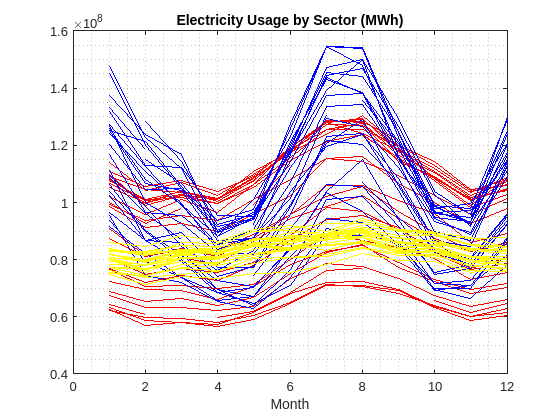

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

plot(com, "r")
hold on
grid minor
plot(res, "b")
plot(ind, "y")
hold off
title("Electricity Usage by Sector (MWh)")
xlabel("Month")

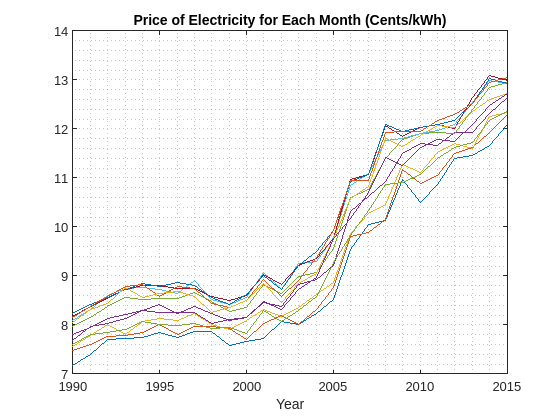


load ../data/electricity.mat
plot(1990:2015, price')
grid minor;
title("Price of Electricity for Each Month (Cents/kWh)")
xlabel("Year")

## Task 1

usage = com + res + ind;

## Task 2

price = price * 1000 / 100;

## Further Practice